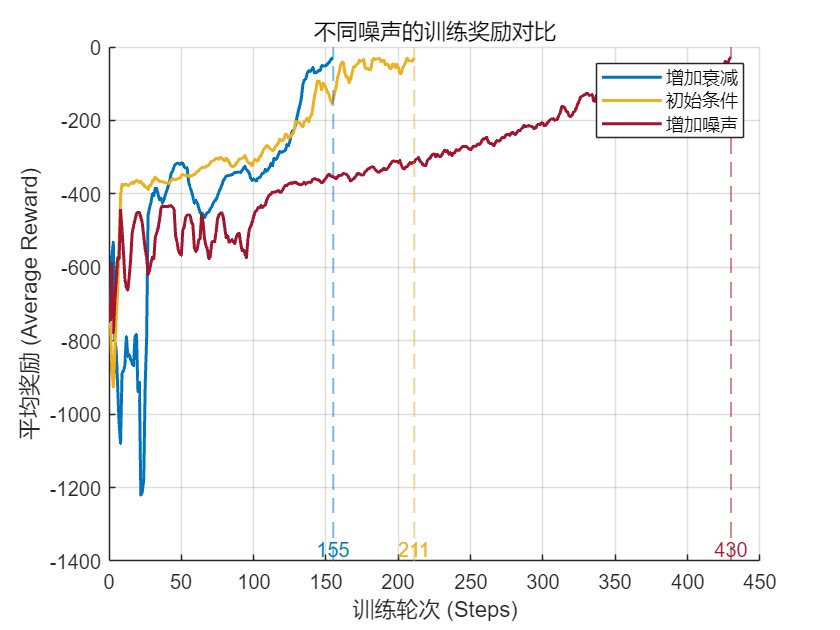

clc
% 生成蓝色渐变（5条线）
colors = [
    0.00 0.45 0.74;  % 蓝
    0.93 0.69 0.13;  % 黄
    0.64 0.08 0.18;  % 红
    
    0.85 0.33 0.10;  % 橙
    0.49 0.18 0.56;  % 紫
    0.47 0.67 0.19;  % 绿
    0.30 0.75 0.93;  % 浅蓝
];
set(gca, 'ColorOrder', colors, 'NextPlot', 'replacechildren'); % 全局配色
plot(1:length(reward1),reward1,'LineWidth', 1.5);
hold on;
plot(1:length(reward2),reward2,'LineWidth', 1.5);
hold on;
plot(1:length(reward3),reward3,'LineWidth', 1.5);
% xlim([1, max([length(reward(:,1)), length(reward(:,2)), length(reward(:,3))])]);

ax = gca; % 获取当前坐标区句柄
ax.XLabel.String = '训练轮次 (Steps)';  % X轴标签
ax.YLabel.String = '平均奖励 (Average Reward)'; % Y轴标签
ax.Title.String = '不同噪声的训练奖励对比'; % 标题

grid on; % 可选：显示网格
% 在每条曲线结束位置添加虚线
xline(length(reward1), '--', 'Color', colors(1,:), 'LineWidth', 1, 'Alpha', 0.5);
xline(length(reward2), '--', 'Color', colors(2,:), 'LineWidth', 1, 'Alpha', 0.5);
xline(length(reward3), '--', 'Color', colors(3,:), 'LineWidth', 1, 'Alpha', 0.5);

% 在虚线上标记x轴的值
text(length(reward1), min(ax.YLim), num2str(length(reward1)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', colors(1,:));
text(length(reward2), min(ax.YLim), num2str(length(reward2)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', colors(2,:));
text(length(reward3), min(ax.YLim), num2str(length(reward3)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', colors(3,:));

legend('增加衰减','初始条件', "增加噪声"); % 添加图例